# Getting Started with AutoActive Research Environment Toolbox

## Description

AutoActive Research Environment Toolbox provides support for writing and reading AutoActive Archives (AAZ) of multiple sensor data and video records. The toolbox also includes support for data import from different sensor types (e.g. Garmin, GaitUp, Catapult) and formats (e.g. gpx, csv). 

AAZ archives can be created, viewed and synchronized in ActivityPresenter, and can be read and written in MATLAB and ActivityPresenter as well as Python. The AutoActive Research Environment Toolbox provides the connection between ActivityPresenter used for data exploration/viewing/time synchronization and MATLAB used for data pre- and postprocessing and data analysis.   

The toolbox uses ArchiveWriter and ArchiveReader to write and read AAZ archives, respectively. The toolbox supports the transformations necessary for converting between MATLAB formats and the AAZ storage formats, its behavior is like a struct element when using it in a MATLAB script. The toolbox is plugin based which means that the user can easly extend the toolbox to support their own use-cases by adding custom plugins. 

## System Requirements

AutoActive Research Environment Toolbox requires a Matlab version r2018b or newer.

The ffmpeg toolbox is required for synchromizing multiple videos within an archive, please see "MultipleVideoSync" documentation.

## Features

- Import of sensor data from multiple sensor types and formats including videos

- Read and write AAZ archives from/to ActivityPresenter

- Convertion between AAZ formats and MATLAB formats

- Merging of data and video from multiple sensor systems for time synchronziation and data analysis/viewing

## Examples

See more examples under the /examples folder and in the 

#### Write an AAZ archive

To create and write an AAZ archive the function ArchiveWriter is used. Create a MATLAB struct consisting of a sine and cosine wave with a time vector in micro seconds:

% create struct of sine and cosine
t = struct();                       % create struct
t.time = (0:1e5:100*1e6)';          % create time vector in micro seconds
t.sine = sin(2*pi*t.time/1e6);      % create sine vector
t.cosi = cos(2*pi*t.time/1e6);      % create cosine vector
t.time = int64(t.time);             % convert the time vector to int64 format -> necessary for ActivityPresenter

Create a second similar struct with a time offset of 1s:

t_off = t;                              % duplicate struct
t_off.time = int64(t_off.time + 1e7);   % add time offset of 1s

Plot the two different sine waveforms:

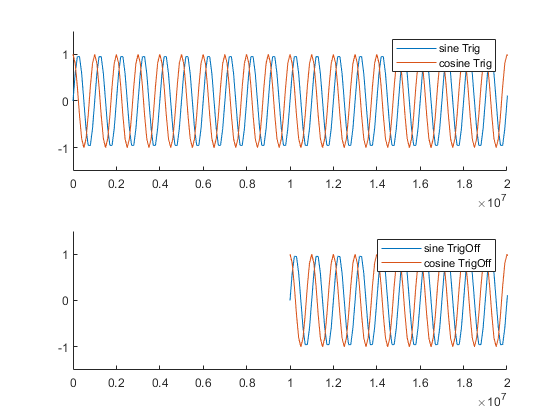

figure; subplot(211);
hold on; plot(t.time,t.sine); plot(t.time,t.cosi)
legend('sine Trig','cosine Trig'); xlim([0 2]*1e7); ylim([-1.5 1.5]);

subplot(212); hold on;
plot(t_off.time,t_off.sine); plot(t_off.time,t_off.cosi)
legend('sine TrigOff','cosine TrigOff'); xlim([0 2]*1e7); ylim([-1.5 1.5]);

Create an AutoActive session of the sine and cosine data:

% create session object
sw = autoactive.Session('testSine');

% create Data folder
sw.Data = autoactive.Folder();    

% convert struct t to table and add to Data folder
sw.Data.Trig = struct2table(t);                             
sw.Data.Trig.Properties.VariableUnits{'time'} = 'Epocms';
sw.Data.Trig.Properties.UserData = struct();        % mandatory metadata for archive

% convert struct t_off to table and add to Data folder
sw.Data.TrigOff = struct2table(t_off);                     
sw.Data.TrigOff.Properties.UserData = struct();     % mandatory metadata for archive

Write AAZ archive with the session 'testSine':

% create archive object and file with name testSine.aaz
aw = autoactive.ArchiveWriter('testSine.aaz');

ArchiveWriter <examples\test_sine\testSine.aaz> - Open


% write session to archive
aw.saveSession(sw);

Session <testSine> - Writing data
autoactive.ArchiveWriter: Saving table <0c55ddd1-4405-4c8c-a936-d86aabbc814e/Data/Trig.parquet>
autoactive.ArchiveWriter: Saving table <0c55ddd1-4405-4c8c-a936-d86aabbc814e/Data/TrigOff.parquet>
autoactive.ArchiveWriter: Saving metadata <0c55ddd1-4405-4c8c-a936-d86aabbc814e/AUTOACTIVE_SESSION.json>
Session <testSine> - End


aw.close()              % close object/file

autoactive.ArchiveWriter: ArchiveWriter <examples\test_sine\testSine.aaz> - Closing


clear aw;               % delete object

#### Read an AAZ archive

To read an AAZ archive into MATLAB the function ArchiveReader is used, creating an MATLAB object. The files and data used in this examples can be found in the toolbox's folder \examples\test_sine, or be created by performing the example on how to write an AAZ archive.

FileName = 'testSine.aaz';                          % name of your AAZ archive in your current MATLAB folder
ArchiveData = autoactive.ArchiveReader(FileName);   % reads the archive into a MATLAB object

The AAZ archive consists of data from at least one measurement session. To list all sessions the function listSessions can be used:

list = ArchiveData.listSessions()                   % to list all sessions within your AAZ archive

autoactive.ArchiveReader: Loading metadata <0c55ddd1-4405-4c8c-a936-d86aabbc814e/AUTOACTIVE_SESSION.json>


list = struct with fields:
      id: '0c55ddd1-4405-4c8c-a936-d86aabbc814e'
    name: 'testSine'


The name of your session is 'testSine', and to read all the data within this session the function openSession can be used:

SessionData = ArchiveData.openSession('testSine')   % reads the session data into a MATLAB object  

autoactive.ArchiveReader: Loading metadata <0c55ddd1-4405-4c8c-a936-d86aabbc814e/AUTOACTIVE_SESSION.json>
Session <0c55ddd1-4405-4c8c-a936-d86aabbc814e> - Reading data
autoactive.ArchiveReader: Loading metadata <0c55ddd1-4405-4c8c-a936-d86aabbc814e/AUTOACTIVE_SESSION.json>
autoactive.ArchiveReader: Loading table <0c55ddd1-4405-4c8c-a936-d86aabbc814e/Data/Trig.parquet>
autoactive.ArchiveReader: Loading table <0c55ddd1-4405-4c8c-a936-d86aabbc814e/Data/TrigOff.parquet>
Session <0c55ddd1-4405-4c8c-a936-d86aabbc814e> - End


SessionData =   Session with fields:

    created: 01-Jul-2020 13:15:15
       name: 'testSine'
       Data: [1×1 autoactive.Folder]


SessionData consists of the time and date of the creation of the session ('created'), the name of the session ('name') and different autoactive folders with sensor data. In this case only one data folder called 'Data' exists. This folder contain the data of two sine and cosine waves with a time offset. The source of the SessionData object contains the information of the file location of the MATLAB script used to create the AAZ archive and this session ('source'). If the AAZ archive was created in ActivityPresenter no source will be given. 

If we look into the 'Data' folder within SessionData we find two tables:

SessionData.Data

ans =   Folder with fields:

       Trig: [1001×3 table]
    TrigOff: [1001×3 table]


The 'Data' folder consists of two tables 'Trig' and 'TrigOff' with 1001 rows and 3 columns each.

SessionData.Data.Trig.Properties.VariableNames

ans = 1×3 cell array
    {'time'}    {'sine'}    {'cosi'}


Both 'Trig' and 'TrigOff' are tables with one column containing 'time'. one  'sine' data and one 'cosi' data. If we plot the two different sine datasets we see that they have an offset in time:

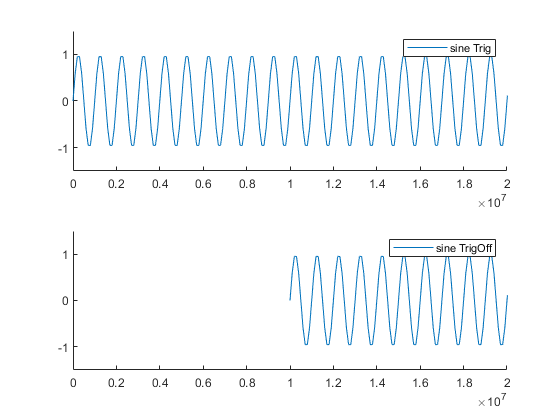

start reading gaitup data
%% Loading 2 Files %%
Reading : C:\Users\siljeja\Documents\autoactive-matlab\MatlabToolbox\examples\gait_example\gaitup_imu\0LF171.BIN
%%%% Reading Header %%%%
------- Physilog : ID = 1171 ---------
> Location : LF ---------
> Type : = 0 / Firmware = 1.2.6/ ---------
> Number of active sensors = 5 
>>> 1) accel / Fs = 128 Hz
>>> 2) gyro / Fs = 128 Hz
>>> 3) baro / Fs = 8 Hz
>>> 4) events / Fs = 128 Hz
>>> 5) radio / Fs = 128 Hz
%%%% Reading data %%%%
Reading part:1/1
Number of sectors: 1103 
>> 0 / 1103 sectors contain invalid data.
Missing sectors: 0 

Reading : C:\Users\siljeja\Documents\autoactive-matlab\MatlabToolbox\examples\gait_example\gaitup_imu\0RF174.BIN
%%%% Reading Header %%%%
------- Physilog : ID = 1174 ---------
> Location : RF ---------
> Type : = 0 / Firmware = 1.2.6/ ---------
> Number of active sensors = 5 
>>> 1) accel / Fs = 128 Hz
>>> 2) gyro / Fs = 128 Hz
>>> 3) baro / Fs = 8 Hz
>>> 4) events / Fs = 128 Hz
>>> 5) radio / Fs = 128 Hz
%%%%

Reading file Gait test 17250 202007011007.csv


Found table with 31228 rows and 19 columns.
Rename column Time to String_time
Calulating new Time column
Converting 31228 rows..done
scanning csv data
Keeping column: time type: int64
Removing text column: String_time
Keeping column: Forward type: double
Keeping column: Sideways type: double
Keeping column: Up type: double
Keeping column: Vel_Dpr_ type: double
Keeping column: Gyr1_d_s_ type: double
Keeping column: Gyr2_d_s_ type: double
Keeping column: Gyr3_d_s_ type: double
Keeping column: Altitude type: double
Keeping column: Vel_av_ type: double
Keeping column: HDOP type: double
Keeping column: VDOP type: double
Keeping column: Longitude type: double
Keeping column: Latitude type: double
Keeping column: HeartRate type: double
Keeping column: Acc_dpr_ type: double
Keeping column: RawVel_ type: double
Removing text column: GPSTime
Removing text column: Var19
done scanning csv data


testing two GPS formats
done reading garmin data
start organizing garmin data
done organizing garmin data


ArchiveWriter <examples\gait_example\Gait_example.aaz> - Open


Session <Gait_example> - Writing data
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a0604519133/gaitup/sensor0LF171/accel.parquet>
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a0604519133/gaitup/sensor0LF171/gyro.parquet>
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a0604519133/gaitup/sensor0LF171/baro.parquet>
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a0604519133/gaitup/sensor0LF171/events.parquet>
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a0604519133/gaitup/sensor0LF171/radio.parquet>
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a0604519133/gaitup/sensor0RF174/accel.parquet>
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a0604519133/gaitup/sensor0RF174/gyro.parquet>
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a0604519133/gaitup/sensor0RF174/baro.parquet>
autoactive.ArchiveWriter: Saving table <e5284b27-9882-445c-b97f-7a060

autoactive.ArchiveWriter: ArchiveWriter <examples\gait_example\Gait_example.aaz> - Closing


Trig = SessionData.Data.Trig;               % create table of 'Trig'
TrigOff = SessionData.Data.TrigOff;         % create table of 'TrigOff'

figure; subplot(211);
hold on; plot(Trig.time,Trig.sine);
legend('sine Trig'); xlim([0 2]*1e7); ylim([-1.5 1.5]);

subplot(212); hold on;
plot(TrigOff.time,TrigOff.sine);
legend('sine TrigOff'); xlim([0 2]*1e7); ylim([-1.5 1.5]);